# Advanced Research Drying Apparatus

# System Analysis Document

System Developer:                 Forest Concepts, LLC

Primary Engineering Staff:     Dr. Jim Dooley, PhD, Project Lead

                                                Christopher Lanning, Design Engineer

                                                Christopher McKiernan, Mechanical Engineer

                                                David Meissner, Mechanical Engineer

## Overview

The United States Department of Agriculture (USDA) listed Small Business Innovation Research (SBIR) Program Phase II included an objective to promote the use of biofuels and non-food biobased products by developing new or improved technologies that will lead to increased production of biofuels, industrial chemicals, and other value-added products from agricultural materials. More specifically, USDA Research Priorities include Agriculturally-related Manufacturing Technology and Alternative and Renewable Energy. 

Forest Concepts, LLC submitted a proposal to address these priorities and to address the risks, primarily related to cost, of drying within the solid and liquid biofuels industry. Through the design and development of an Advanced Research Drying Apparatus (aRDA) research questions will be addressed and reveal practical solutions to reducing less effective and costly industry methods. A preliminary view of the aRDA is shown in Figure 1: Draft System CAD Overview.

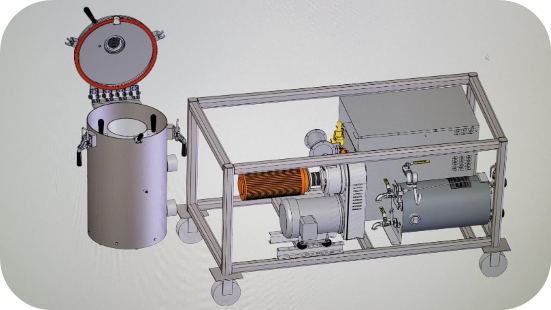

Figure 1: Draft System CAD Overview

## Glossary and Acronyms

    **aRDA: **Advanced Research Drying Apparatus

    **freestream:** also referred to as upstream fluid velocity

    **RDA: **Research Drying Apparatus

    ** SBIR: **Small Business Innovation Research

    **USDA: **United States Department of Agriculture

    **Wet basis: **Refers to a particular method of measuring moisture content

    **equilibrium vapor pressure, **$p_s$**: **See saturation vapor pressure

    **enthalpy of condensation:** the energy required for a direct phase transition from gaseous to liquid state. Equal in quantity to and with opposite sign of the enthaply of vaporization.

    **enthalpy of vaporization: **$\Delta H_{\textrm{vap}}$ the energy required for a direct phase transition from liquid and gaseous state. 

    **heat of condensation:** See enthalpy of condensation.

    **heat of evaporation: **Equivalent to enthalpy of vaporization.

    **heat of vaporization: **$\Delta H_{\textrm{vap}}$. Equivalent to enthalpy of vaporization.

    **humidity ratio: **See specific humidity.

    **isobaric process: **A thermodynamic process in which the pressure remains constant. (Note: Isobaric expansion of a gas requires heat transfer to keep the pressure constant.)

    **isochoric process: **a thermodynamic process in which the volume remains constant. (Note: Here the system does no work. The only change is that the gas gains internal energy.)

    **latent heat of vaporization: **Equivalent to enthalpy of vaporization.

    **molar enthalpy of vaporization: **The same quantity as enthalpy of vaporization but stated in J/mol or kJ/mol.

    **mole fraction of water vapor, :** The mole fraction of water vapor is the ratio of the number of moles of water vapor in the moist air to the total number of moles of dry air and water vapor.

    **saturation vapor pressure (equilibrium vapor pressure), **$p_s$: The vapor pressure of a system, at a given temperature, for which the vapor of a substance is in equilibrium with a plane surface of that substances's pure liquid or solid phase; that is, the vapor pressure of a system that has attained saturation but not supersaturation.

    **specific heat of vaporization: **The same quantity as enthalpy of vaporization but stated in kJ/kg or J/g.

    **specific humidity, **$q$: (of an air sample) The ratio of the weight of water vapor contained in the sample compared to the weight of the dry air in the sample. (Also referred to as humidity ratio.)

    **vapor pressure, **$P_v$: The pressure exerted by the molecules of a given vapor. For a vapor mixed with other vapors or gases, it is that vapor's contribution to the total pressure (i.e. its partial pressure). Here, it denotes exclusively the partial pressure of water vapor in the systems contained air mass.

## Variables

Notation used for variables in mathematical expressions are shown on the left. "MATLAB variable" names are shown in parentheses.

    $m_a =$ mass of dry air (`m_a`)

    $m_v =$ mass of vapor (`m_v`)

    $M_{\textrm{air}} =$ molecular weight of dry air, $\frac{\textrm{kg}}{\textrm{mol}}$

    $M_{\textrm{vapor}} =$ molecular weight of water vapor (moist air), $\frac{\textrm{kg}}{\textrm{mol}}$

    $n_a =$ Number of moles of dry air (`n_a`)

    $n_v =$ Number of moles of water vapor (`n_v`)

    $P_g =$ Pressure of air/vapor mixture, $\textrm{kPa}$ (`P_g`)

    $P_t =$ Pressure (or total pressure), $\textrm{kPa}$ (`P_t`)

    $P_s =$ Saturation vapor pressure, $\textrm{kPa}$ (`P_s`)

    $P_v =$ Vapor ressure, $\textrm{kPa}$ (`P_v`)

    $\phi =$ Relative humidity (May also be written as $\textrm{RH}$.) (`phi`)

    $q=\;$Humidity ratio (`q`)

    $R=$ Ideal gas constant, $\frac{\textrm{Pa}{\;\cdot m}^2 }{K\cdot \textrm{mol}}$ (`R`)

    $R_a =$ Specific gas constant for dry air, $\frac{J}{\textrm{kg}\cdot K}$ (`R_a`)

    $R_v =$ Specific gas constant for water vapor, $\frac{J}{\textrm{kg}\cdot K}$ (`R_v`)

    $\textrm{RH}=$ Relative Humidity (May also be written as $\phi$.) (`phi`)

    $T_C =$ Temperature, $C^{\circ }$ (`T_c`)

    $T_{\textrm{dp}} =$ Dew point temperature, $C^{\circ }$ (`T_dp`)

    $T=$ temperature, $K^{\circ }$ (`T`)

    $V_a =$ Volume of dry air, $m^3$ (`V_a`)

    $V_g =$ Volume of total gas mixture, $m^3$ (`V_g`)

    $V_t =$ Total volume, $m^3$ (`V_t`)

    $V_v =$ volume of water vapor, $m^3$(`V_v`)

    $w=$ mixing ratio (or mole fraction) of water vapor to dry air, $\frac{\textrm{mol}}{\textrm{mol}}$ (`w`)

## Mathematical Representation

### State-space Representation

The system is assumed to be $\rho_s \;$continuous and time-invariant, and without feedthrough, thus it may be represented using state-space representation as follows


$$\begin{array}{l}
\dot{\mathit{\mathbf{x}}} \left(t\right)=\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\\
\mathit{\mathbf{y}}\left(t\right)=\textrm{Cx}\left(t\right)
\end{array}$$


where $\mathit{\mathbf{x}}\left(t\right)$ is the time-dependent state vector, $\mathit{\mathbf{y}}\left(t\right)$ is the time-dependent output vector, $u\left(t\right)$ is the time-dependent input vector, $\mathit{\mathbf{A}}$is the state or system matrix, $\mathit{\mathbf{B}}$ is the input matrix, and $\mathit{\mathbf{C}}$ is the output matrix.

The first task required with this system is to take measurements of specific variables that will allow us to definitely calculate each of the other variables or parameters of the system. In this case, the system is designed to measure $T$, temperature ($K^{\circ }$), $P$, pressure ($\textrm{kPa}$), and $\phi$, relative humidity all internal to the system.

The state vector, $\mathit{\mathbf{x}}$, of the system is


$$\mathit{\mathbf{x}}=\left\lbrack \begin{array}{c}
T\\
V_g 
\end{array}\right\rbrack$$


The ability to control system parameters is essential to safety and operation. In this case, the system is designed to control $\omega_b$ , the commanded angular rate of the blower (rad/s), $\theta$, the commanded injection valve angle (rad), $\psi$, the commanded recirculation valve angle (rad), $P_{h\left(\textrm{main}\right)}$, the power sent to the main heater (Watts), and $P_{h\left(\textrm{cond}\right)}$, the power sent to the condensation heater (Watts).

The input or control vector, $\mathit{\mathbf{u}}$, with dimensions $p\times 1$ is


$$\mathit{\mathbf{u}}=\left\lbrack \begin{array}{c}
\omega_b \\
\theta \\
\psi \\
P_{h\left(\textrm{main}\right)} \\
P_{h\left(\textrm{cond}\right)} 
\end{array}\right\rbrack$$


In choosing

The output vector, $\mathit{\mathbf{y}}$, of the system with dimensions $q\times \;1$ is


$$\mathbf{y} =\left[ \matrix{V_a \cr V_v \cr P_a \cr P_v \cr P_s \cr m_g \cr m_a \cr m_v \cr \rho_g \cr \rho_a \cr \rho_v \cr \rho_{a(mix)} \cr \rho_{v(mix)} \cr q \cr \phi } \right] $$


The system matrix, $A$, which may be determined by system identification techniques, has dimensions $n\times n$ and the following form.


$$\mathbf{A} = \left[ \matrix{A_{11} & A_{12} & \cdots & A_{1n} \cr A_{21} & A_{22} &  & \vdots \cr \vdots & & \ddots \cr A_{n1} & \cdots & & A_{nn} } \right]$$


The input matrix, $\mathit{\mathbf{B}}$, with dimensions $n\times p$

*in development*

The output matrix, $\mathit{\mathbf{C}}$, has dimensions $q\times n$ is


$$\mathbf{C} = \left[ \matrix{0 & 0 & 1 \cr \frac{-m_vR_v}{P_g} & 0 & 1 \cr \frac{m_vR_v}{P_g}&0&0   } \right]$$


% Setup
clear; close all; clc
addpath('C:\Users\dmeissner\OneDrive - Forest Concepts\code\air_water_steam')

## Measurements

In order to calculate all of the 

T_c = 20;		    % C, Temperature (20 C = 68 F = 293.15 K)
T = T_c + 273.15;   % K
P_t = 101.325;		% kPa, Total Pressure (101.325 kPa = 1 atm = 14.696 psi)
phi = 0.50;         % Relative humidity

## Constants

R = 8.314e-3;	    % Ideal Gas Constant (kPa*m^2/(K*mol)), or J/(K*mol)
R_a = 287.058;      % J/(kg*K), Specific Gas Constant, dry air
R_v = 461.495;      % J/(kg*K), Specific Gas Constant, water vapor

## Design

The system is designed to contain a fixed volume of 1 cubic meter.

V_g = 1;  % m^3

## Pressure

Assuming the system operates below saturation, the total pressure is equal the pressure of the air/vapor gas mixture.


$$P_g =P_t$$
                                                                                                                 

P_g = P_t;  % kPa

## Humidity Ratio

To calculate humidity ratio from relative humidity, we need to...

- Determine saturation vapor pressure at the current saturation pressure, $P_s$, from the steam tables (IAPWS IF-97). The tables utilized here were provided by Magnus Holmgren in the form of a MATLAB function, `Xsteam`.


$$P_s=f(T_c)$$


% P_s = XSteam('psat_T', T_c)
% Here use T in Kelvin
if T < 647.096 && T > 273.15
    teta = T - 0.23855557567849 / (T - 650.17534844798);
    a = teta ^ 2 + 1167.0521452767 * teta - 724213.16703206;
    B = -17.073846940092 * teta ^ 2 + 12020.82470247 * teta - 3232555.0322333;
    C = 14.91510861353 * teta ^ 2 - 4823.2657361591 * teta + 405113.40542057;
    p4_T = (2 * C / (-B + (B ^ 2 - 4 * a * C) ^ 0.5)) ^ 4;
    P_s = p4_T * 10  % bar to MPa
else
    error('Temperature out of valid range.')
end

P_s = 0.0234

q = ((phi * P_s) * V_g / (R_v * T))/(P_g * (V_g - (m_v * R_v * T / P_g)) / (R_a * T))

- Calculate partial pressure of the vapor pressure, $P_v$, from measured relative humidity ($\phi$ or `phi`) and the calculated saturation vapor pressure.

$\phi =\frac{P_v }{P_s }$                                                                                                 (12)

P_v = phi * P_s

P_v = 0.0117

### Ideal Gas Relationships

The ideal gas law provides the following relationships are relatively low pressures (approx. 0 - 1000 bar) and relatively high temperatures (approx. 0 - 2000 C). The aRDA system will operate at or near atmospheric pressure and at temperatures near the standard temperature but at no point above a few hundred degrees Celsius, so the effects of compressibility are assumed neglibible.

- Calculate the mass of the water vapor, $m_v \;$, from the ideal gas law relation

$P_v V_g =m_v R_v T$                                                                                                  (11)

m_v = P_v * V_g / (R_v * T)

m_v = 8.6454e-08

- Calculate the partial volume of th water vapor, $V_v$, from the ideal gas law relation


$$P_g V_v =m_v R_v T$$
                                                                                                        

V_v = m_v * R_v * T / P_g

V_v = 1.1543e-04

### Volume

The volume of a mixture of dry air and water vapor is the sum of its constituents.

$V_g =V_a +V_v$                                                                                                     (1)

- Calculate the partial volume of the dry air, $V_a$, from the calculated partial volume of the water vapor.

V_a = V_g - V_v

V_a = 0.9999

- Calculate the mass of the dry air, $m_a$, from the ideal gas relation 

$P_g V_a =m_a R_a T$                                                                                                  (2)

m_a = P_g * V_a / (R_a * T)

m_a = 0.0012

- Calculate the partial pressure of the dry air, $P_a$, from the ideal gas relation

$P_a V_g =m_a R_a T$                                                                                                (10)

P_a = m_a * R_a * T / V_g

P_a = 101.3133

Humidity ratio, or specific humidity, is defined as the mass of water vapor in the mixture divided by the mass of the dry air in the mixture.

$$q = \frac{m_v}{m_{a}}$                                                                                                         (4)

q = m_v/m_a

q = 7.1809e-05

## Additional quantities

$\rho_a =\frac{m_a }{V_a }$                                                                                                (5)

rho_a = m_a / V_a  % kg/m^3

rho_a = 0.0012

$\rho_v =\frac{m_v }{V_v }$                                                                                                (6)

rho_v = m_v / V_v  % kg/m^3

rho_v = 7.4896e-04

$m_g =m_a +m_v$                                                                                                 (7)

$m_t =m_g +m_w$                                                                                              (23)

if phi < 0.95
    m_w = 0;
else
    error('Current equations do not allow for relative humidity at or above 95%.')
end
m_g = m_a + m_v

m_g = 0.0012

m_t = m_g + m_w

m_t = 0.0012

$\rho_g =\frac{m_g }{V_g }$                                                                                                  (22)

rho_g = m_g / V_g

rho_g = 0.0012

$\rho_{a\left(\textrm{mix}\right)} =\frac{m_a }{V_g }$                                                                                                    (8)

rho_a_mix = m_a / V_g

rho_a_mix = 0.0012

$\rho_{v\left(\textrm{mix}\right)} =\frac{m_v }{V_g }$                                                                                                   (9)

## Save Time and Results

stoptime = datetime('now');
fprintf('Stop time: %s \n', datestr(stoptime))

Stop time: 14-May-2021 13:13:32 


save results.mat

## Cleanup

rmpath('C:\Users\dmeissner\OneDrive - Forest Concepts\code\air_water_steam')